# Example 0: Single stratigraphic case + analysis (2D)

This is a complete introductory example. It shows how to load the appropriate MRST modules, define the inputs according to a given faulted stratigraphy, and generate the output permeability distributions. A comprehensive analysis of the results is also shown. The algorithm is run in 2D mode.

We first make sure that the workspace is clean:

clear
close all force

## 1. Load Required MRST Modules

First, navigate to the mrst folder and run `startup.m`. We can then load the appropriate modules for generating MRST grids and upscale the permeability:

mrstModule add mrst-gui coarsegrid upscaling incomp mpfa
mrstVerbose off

## 2. Define Model and Upscale Permeability

% 2.1 Mandatory input parameters
% Footwall first and hangingwall next, e.g. {[footwall, FW], [hangingwall, HW]}. 
% We need to define the layer thickness, clay content, layer dip angle, fault 
% dip angle, faulting depth, and burial depth. Further details about input parameter 
% formatting, etc can always be checked from the documentation in the classes 
% and functions.
thickness = {repelem(25, 1, 4), [5 10 15 10 20 10 10 5 15]};                % [m]
vcl       = {[0.1 0.4 0.2 0.5], ...
             [0.3 0.6 0.1 0.7 0.2 0.8 0.3 0.9 0.1]};                        % fraction [-]
dip       = [0, -5];                                                        % [deg.]
faultDip  = 70;                                                             % [deg.]
zf        = [500, 500];                                                     % [FW, HW], [m]
zmax      = {repelem(2000, numel(vcl{1})), repelem(2000, numel(vcl{2}))};   % {FW, HW}
dim       = 2;                    % dimensions (2 = 2D, 3 = 3D)
unit_plot = 'm';                  % 'm' or 'cm' depending on fault dimensions

% 2.2 Optional input parameters
% In this case, we indicate a maximum fault material permeability of and a correlation 
% coefficient for dependent variables:
maxPerm = 1000;                 % [mD]
rho     = 0.6;                  % Corr. coeff. for multivariate distributions

% 2.3 Flow upscaling options and number of simulations
U.useAcceleration = 1;          % 1 requires MEX setup, 0 otherwise (slower for MPFA).
U.method          = 'mpfa';     % 'tpfa' recommended if useAcceleration = 0
U.outflux         = 0;          % compare outflux of fine and upscaled model
U.ARcheck         = 0;          % check if Perm obtained with grid with aspect ratio of 
                                % only 5 gives same output.
U.coarseDims      = [1 1 1];    % Mandatory one cell if 2D
Nsim              = 1000;       % Number of simulations/realizations

% 2.4 Define Stratigraphy and FaultedSection objects
% Organize the input parameters in HW and FW, and use that info to create a 
% FaultedSection object which contains all required information.
% FW and HW
footwall = Stratigraphy(thickness{1}, vcl{1}, 'Dip', dip(1), ...
                        'DepthFaulting', zf(1), 'DepthBurial', zmax{1});
hangingwall = Stratigraphy(thickness{2}, vcl{2}, 'Dip', dip(2), 'IsHW', 1, ...
                           'NumLayersFW', footwall.NumLayers, ...
                           'DepthFaulting', zf(2), 'DepthBurial', zmax{2});

% Instantiate FaultedSection object (Strati in Faulted Section)
mySect = FaultedSection(footwall, hangingwall, faultDip, 'maxPerm', maxPerm);

% 2.5 Get material distributions
% We use the inputs to constrain the ranges and distributions for each of the 
% intermediate variables.
% Get material property distributions
mySect = mySect.getMatPropDistr();

% 2.6 Get base grid
% We generate a base grid with arbitrary thickness, to be modified at each
% realization (faster than generating n grids from scratch)
D = sum(mySect.Tap(mySect.FW.Id));
T0 = 1;
G0 = makeFaultGrid(T0, D);


% 2.7 Generate intermediate variable samples, calculate smear dimensions and upscale permeability
% We create two container variables (faults and smears) where we'll save all 
% data for each realization. For each realization, the code defines a Fault object, 
% generates intermediate variable samples, calculates the smear dimensions, and, 
% within upscaleSmearPerm, generates a fault material distribution consistent 
% with the inputs and upscales the permeability.
% Generate fault object with properties for each realization
faults = cell(Nsim, 1);
smears = cell(Nsim, 1);
tstart = tic;
parfor n=1:Nsim    % parfor allowed if you have the parallel computing toolbox
%for n=1:Nsim
    myFault = Fault2D(mySect, faultDip);
    
    % Get material property (intermediate variable) samples, and fix 
    % along-strike thickness of current realization if 3D.
    myFault = myFault.getMaterialProperties(mySect, 'corrCoef', rho);
    
    % Update grid dimensions with sampled fault thickness
    G = updateGrid(G0, myFault.MatProps.thick);
    
    % Generate smear object with T, Tap, L, Lmax
    smear = Smear(mySect, myFault, G, 1);
    
    % Place fault materials and assign cell-based properties
    myFault = myFault.placeMaterials(mySect, smear, G);
    
    % Compute upscaled permeability distribution
    myFault = myFault.upscaleProps(G, U);
    
    % Save result
    faults{n} = myFault;
    smears{n} = smear;
    if mod(n, 100) == 0
        disp(['Simulation ' num2str(n) ' / ' num2str(Nsim) ' completed.'])
    end
end

Simulation 300 / 1000 completed.
Simulation 100 / 1000 completed.
Simulation 400 / 1000 completed.
Simulation 200 / 1000 completed.
Simulation 500 / 1000 completed.
Simulation 600 / 1000 completed.
Simulation 700 / 1000 completed.
Simulation 800 / 1000 completed.
Simulation 900 / 1000 completed.
Simulation 1000 / 1000 completed.


telapsed = toc(tstart);

## 3. Output Analysis

3.1 Visualize stratigraphy and fault (with thickness corresponding to 1st realization)

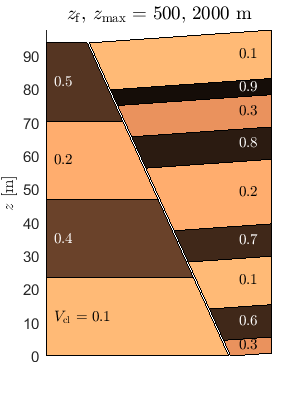

mySect.plotStrati(faults{1}.MatProps.thick, faultDip, unit_plot);  

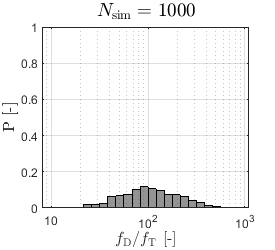

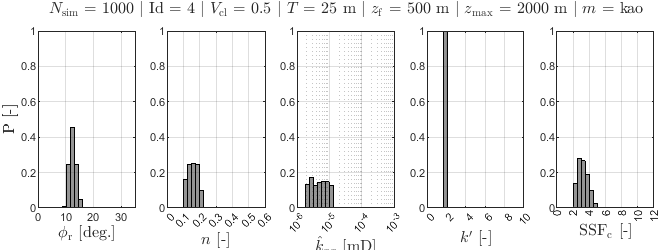

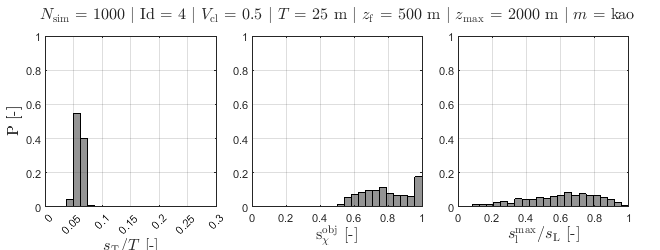


% 3.2 Visualize intermediate variables
% We define a given parent material (id from 1 to n of materials in stratigraphy), 
% and generate histograms and correlation matrix plots.
layerId = 4;                                            
plotMatPropsHist(faults, smears, mySect, layerId, dim) 

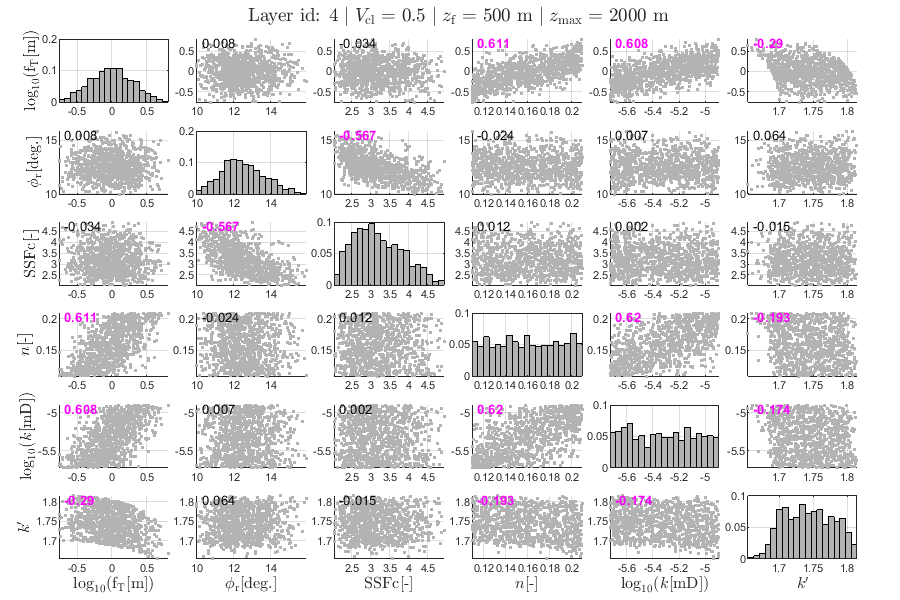

% MatProps correlations
[R, P] = plotMatPropsCorr(faults, mySect, layerId, dim);

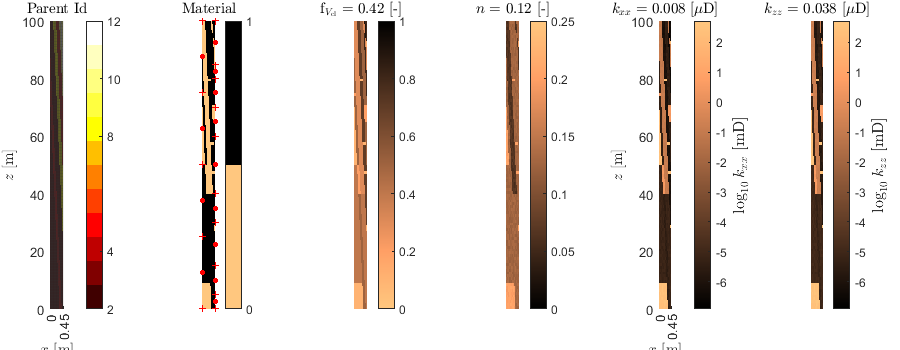


% 3.3 Visualize fault materials
% Visualization for one realization. Choice can be 'randm' (random), 'maxX' 
% (realization with maximum upscaled permeability in across the fault), 'minX', 
% 'maxZ' or 'minZ'.
% General fault materials and perm view
plotId = selectSimId('randm', faults, Nsim);                % simulation index
faults{plotId}.plotMaterials(mySect, G0) 

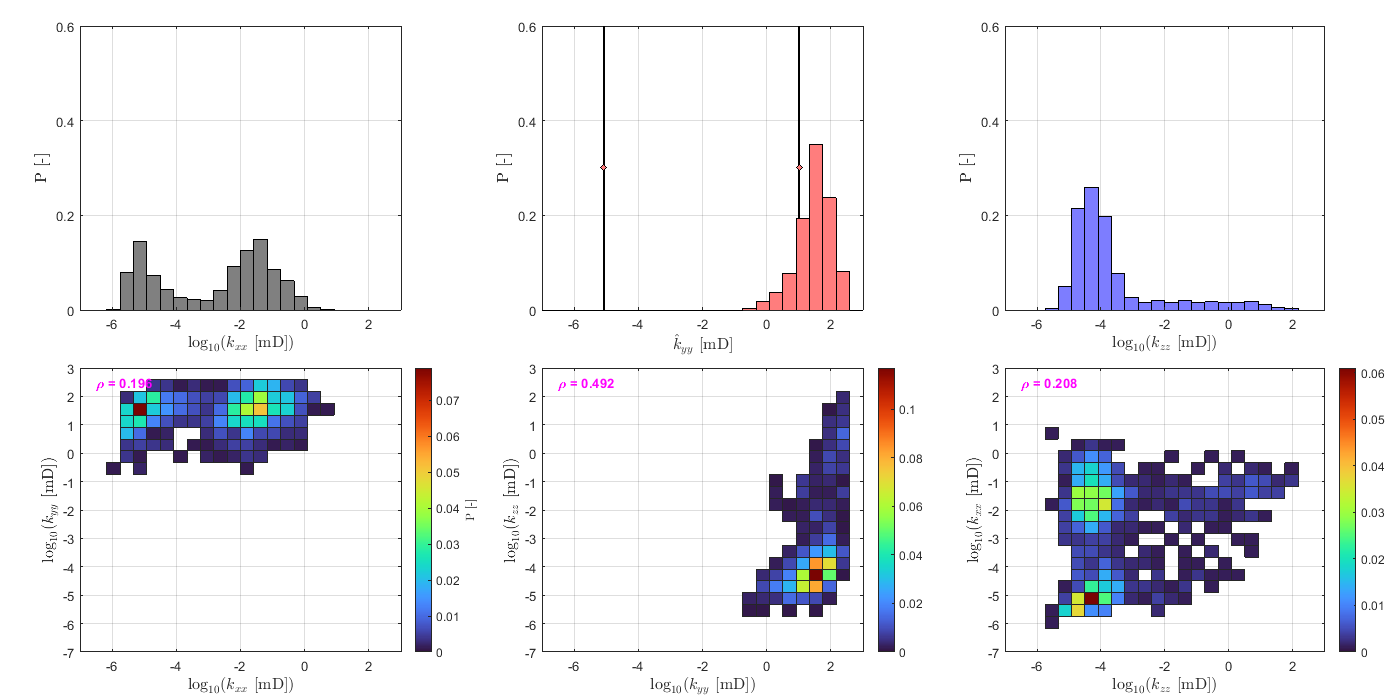


% 3.4. Visualize upscaled permeability
% Plot upscaled permeability distributions (all simulations)
plotUpscaledPerm(faults, dim)